% Définir le chemin d'accès racine qui contient les images
rootFolderPath = 'Matlab/data';

% Définir le filtre de fichiers pour n'inclure que les images
fileFilter = ['*.jpg'];

% Trouver tous les fichiers correspondant au filtre dans tous les sous-dossiers
imageFiles = dir(fullfile(rootFolderPath, '**', fileFilter));

% Pour chaque fichier d'image trouvé
for i = 1:length(imageFiles)
    % Construire le chemin d'accès complet pour le fichier
    imagePath = fullfile(imageFiles(i).folder, imageFiles(i).name);
    
    % Lire l'image
    image = imread(imagePath);
    
    % Redimensionner l'image à 224x224
    image_resized = imresize(image, [224, 224]);
    
    % Sauvegarder l'image redimensionnée au même emplacement
    imwrite(image_resized, imagePath);
end


allImages = imageDatastore(fullfile('Matlab/','data/'),...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');

rng default
[imgsTrain,imgsValidation] = splitEachLabel(allImages,0.8,'randomized');
disp(['Number of training images: ',num2str(numel(imgsTrain.Files))]);

Number of training images: 3241


net = googlenet;

graphs

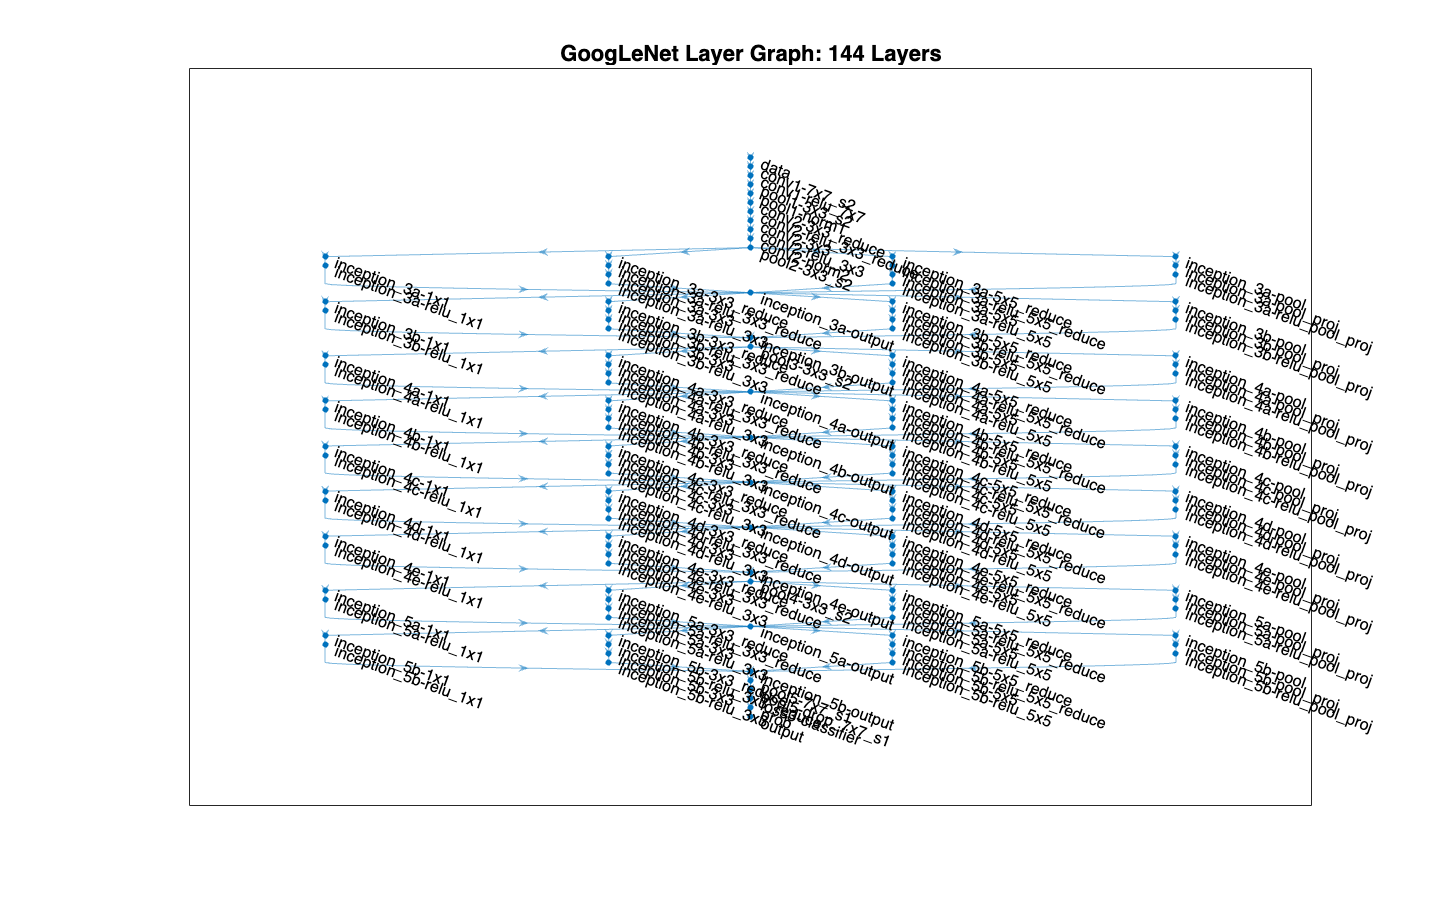

lgraph = layerGraph(net);
numberOfLayers = numel(lgraph.Layers);
figure('Units','normalized','Position',[0.1 0.1 0.8 0.8]);
plot(lgraph)
title(['GoogLeNet Layer Graph: ',num2str(numberOfLayers),' Layers']);

net.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'data'
                 InputSize: [224 224 3]
        SplitComplexInputs: 0

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [224×224×3 single]


newDropoutLayer = dropoutLayer(0.6,'Name','new_Dropout');
lgraph = replaceLayer(lgraph,['pool5-dro' ...
    'p_7x7_s1'],newDropoutLayer);

numClasses = numel(categories(imgsTrain.Labels));
newConnectedLayer = fullyConnectedLayer(numClasses,'Name','new_fc',...
    'WeightLearnRateFactor',5,'BiasLearnRateFactor',5);
lgraph = replaceLayer(lgraph,'loss3-classifier',newConnectedLayer);

Error using nnet.cnn.LayerGraph>iValidateLayerName
Layer 'loss3-classifier' does not exist.

Error in nnet.cnn.LayerGraph/replaceLayer (line 444)
            iValidateLayerName(layerName, existingLayerNames);


newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'output',newClassLayer);


options = trainingOptions('sgdm',...
    'MiniBatchSize', 32,...
    'MaxEpochs', 20,...
    'InitialLearnRate', 1e-4,...
    'ValidationData', imgsValidation,...
    'ValidationFrequency', 10,...
    'Verbose', 1,...
    'ExecutionEnvironment', 'gpu',... % Utilisation du GPU
    'Plots', 'training-progress',...
    'UseParallel', true); % Parallélisation

Error using nnet.cnn.TrainingOptionsSGDM
'UseParallel' is not an option for solver 'sgdm'.

Error in trainingOptions (line 340)
    opts = nnet.cnn.TrainingOptionsSGDM(varargin{:});

rng default

trainedGN = trainNetwork(imgsTrain,lgraph,options);

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:01:44 |       30.00% |       34.65% |       2.1444 |       1.3480 |      1.0000e-04 |
|       1 |          20 |       00:04:37 |       50.00% |       33.91% |       0.9906 |       1.1707 |      1.0000e-04 |
|       1 |          40 |       00:07:21 |       30.00% |       33.66% |       1.0944 |       1.0990 |      1.0000e-04 |
|       1 |          50 |       00:07:58 |       40.00% |              |       1.0817 |              |      1.0000